**Anharmonic motion analysis**

To start with, let's look at an undamped anharmonic oscillator and see what the motion is like.

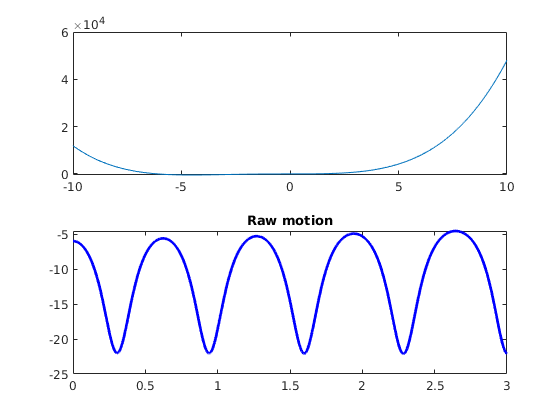

%% Setting up Parameters
X0 = [-6 0];
trap_freq = 1.213; %HERTZ
T_win = linspace(0,3,1000);

P = [0.5 (10) 0 18 3];%[m, spring, damping, cubic, quartic] 
Xrng = linspace(-10,10,500);
trap_shape = polyval(fliplr(P),Xrng);
% Input designed to keep trap freq constant; fixes k given m.

fit_coef_names = {'Freq','Phase','Damping rate','Offset'};
%Solve for evolution of nonlinear oscillator

[t,Y] = ode45(@(t,X) trap_DE(t,X,P),T_win,X0);
f1 = figure;
figure(f1);
subplot(2,1,1)
plot(Xrng,trap_shape)
hold on
subplot(2,1,2)
plot(t,Y(:,1),'b','LineWidth',2)
title('Raw motion')
hold on

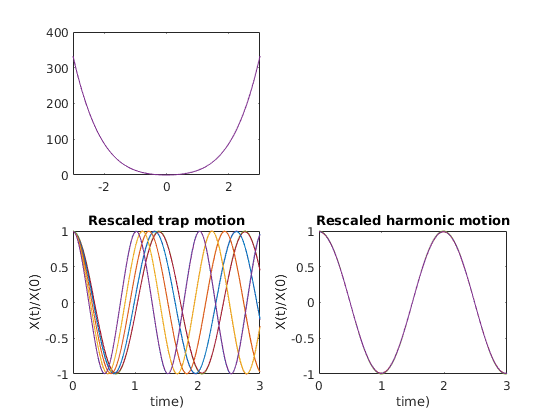

%Setup
IC = -5:5;
Y0 = [0 0];
P1 = [0.5 10 0 0 3];%[m, spring, damping, cubic, quartic] 
Xrng = linspace(-3,3,500);
trap_shape = polyval([P1([5,4,2]),0,0],Xrng); %Assuming no linear bias & zero offset
[minim,loc]=min(trap_shape);
%Initialization
YAH = zeros(numel(IC),numel(T_win));

figure();
for i =1:numel(IC)
    y0 = Y0;
    y0(1) = Xrng(loc)+IC(i); %displacement relative to trap bottom
    [t,Y] = ode45(@(t,X) trap_DE(t,X,P1),T_win,y0);
    YAH(i,:) = Y(:,1)/IC(i);
    subplot(2,2,1)
    plot(Xrng,trap_shape)
    hold on
    subplot(2,2,3)
    plot(t,Y(:,1)/IC(i))
    title('Rescaled trap motion')
    xlabel('time)')
    ylabel('X(t)/X(0)')
    hold on
    [t,Yh] = ode45(@(t,X) trap_DE(t,X,[1 10 0 0 0]),T_win,y0);
    subplot(2,2,4)
    plot(t,Yh(:,1)/IC(i))
    title('Rescaled harmonic motion')
    xlabel('time)')
    ylabel('X(t)/X(0)')
    hold on
end

Things to notice:

- Breaking the trap symmetry with a cubic term means the motion depends on the initial amplitude. This is not true for the harmonic case (adjacent. Yes, there are just as many curves there.)

- Adding a quartic term produces a frequency shift with changing amplitude!

- Let's try fitting a quartic-perturbed trap with a sine wave.

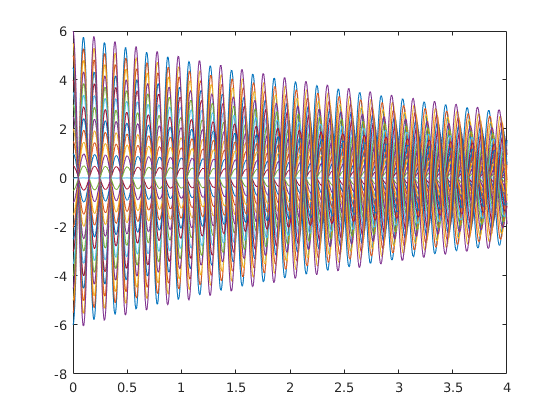

IC = linspace(-6,6,25);
Y0 = [0 0];
T_rng = linspace(0,4,2000);
m=1;
omega0 = 5;
P2 = [m m*(2*pi*omega0)^2 0.2 14 16];%[m, spring, damping, cubic, quartic] 
Xrng = linspace(-3,3,1000);
trap_shape = polyval([P2([5,4,2]),0,0],Xrng); %Assuming no linear bias & zero offset
[minim,loc]=min(trap_shape);
%Initialization
YAH = zeros(numel(IC),numel(T_rng));

figure();
fit_f = zeros(size(IC));

for i =1:numel(IC) 
% i=2;
    y0 = Y0;
    y0(1) = Xrng(loc)+IC(i); %displacement relative to trap bottom
    [t,Y] = ode45(@(t,X) trap_DE(t,X,P2),T_rng,y0);
    beta0 = [omega0,0,0,0,y0(1)].*(0.99+0.01*randn(1,5));
    anh_fit = fitnlm(t,Y(:,1),@damped_sine,beta0);
    fit_f(i) = abs(anh_fit.Coefficients.Estimate(1));
%     subplot(3,1,1)
    plot(t,Y(:,1))
    hold on
%     subplot(3,1,2)
%     plot(t,Y(:,1)-damped_sine(anh_fit.Coefficients.Estimate,t))
%     hold on
end

Observations

- Damping kills anharmonicity and pushes trap freq back towards natural frequency?

- Anharmonic terms both seem to add a quadratic dependence of the fit frequency on the amplitude

- Damped anharmonic oscillators are real hard to fit with damped sine waves

Some systematic investigations for undamped and damped (harder!):

- How does fitted freq vary with amplitude and quartic term? i.e. what is the coefficient of this apparent quadratic term?

- How about the cubic term?

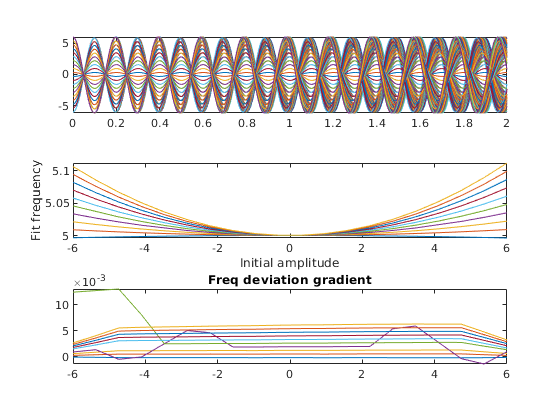

IC = linspace(-6,6,20);
T_rng = linspace(0,2,2000);
terms = linspace(0,10,10);
fit_fs = zeros(length(IC),1);
P3 = [m m*(2*pi*omega0)^2 0 14 16];%[m, spring, damping, cubic, quartic] 
figure()
grad_est = zeros(size(terms));
grad_err = zeros(size(terms));
for j=1:length(terms)
    subplot(3,1,1)
    for i =1:numel(IC) 
        P_loc = P3;
        P_loc(5) = terms(j);
        y0 = Y0;
        y0(1) = Xrng(loc)+IC(i); %displacement relative to trap bottom        
        [t,Y] = ode45(@(t,X) trap_DE(t,X,P_loc),T_rng,y0);
        beta0 = [omega0,0,0,0,y0(1)].*(0.99+0.01*randn(1,5));
        anh_fit = fitnlm(t,Y(:,1),@damped_sine,beta0);
        fit_fs(i) = abs(anh_fit.Coefficients.Estimate(1));
        plot(t,Y(:,1))
        hold on
    end
    subplot(3,1,2)
    fs_err = (fit_fs - omega0)/omega0;
    fs_filt = abs(fs_err)<0.5 & abs(fs_err)>-0.5;
    plot(IC(fs_filt),fit_fs(fs_filt))
    xlabel('Initial amplitude')
    ylabel('Fit frequency')
    hold on;
    subplot(3,1,3)
    grad_est = gradient(fit_fs(fs_filt),mean(diff(IC)));
    quad_est = gradient(grad_est,mean(diff(IC)));
    plot(IC(fs_filt),quad_est)
    title('Freq deviation gradient')
    hold on
%     grad_err(j) = std(diff(diff(fit_fs(fs_filt))/mean(IC(fs_filt))));
end